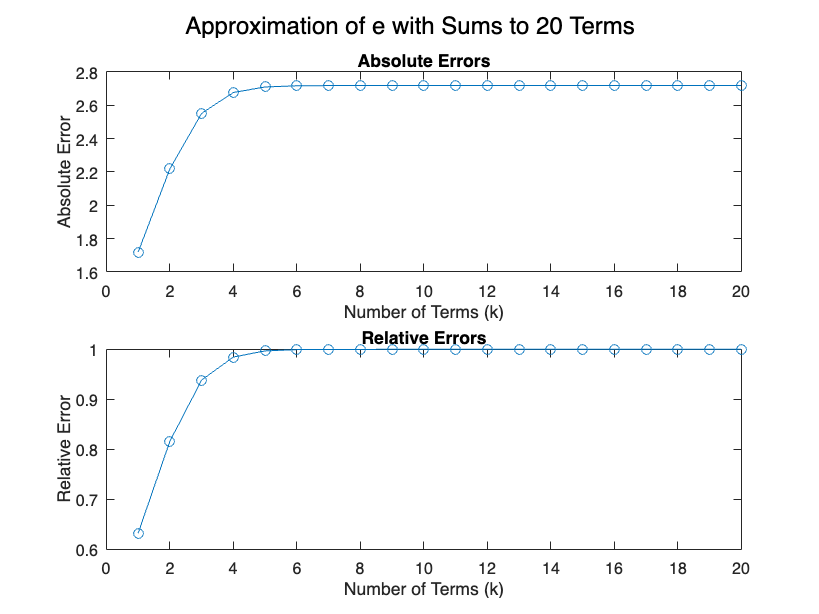

% Calculations and plotting

% Array to store results
k_values = 1:20;
absolute_errors = zeros(size(k_values));
relative_errors = zeros(size(k_values));

% Calculate errors for different values of k
for i = 1:length(k_values)
    k = k_values(i);
    e_k = approximate_e(k);
    
    % Absolute and relative errors
    absolute_errors(i) = abs(e_true - e_k);
    relative_errors(i) = absolute_errors(i) / abs(e_true);
end


% True value of e
e_true = exp(1);

figure;

subplot(2, 1, 1);
plot(k_values, absolute_errors, 'o-');
title('Absolute Errors');
xlabel('Number of Terms (k)');
ylabel('Absolute Error');

subplot(2, 1, 2);
plot(k_values, relative_errors, 'o-');
title('Relative Errors');
xlabel('Number of Terms (k)');
ylabel('Relative Error');

sgtitle('Approximation of e with Sums to 20 Terms');

function fact = factorial(n)
    if n == 0 || n == 1
        fact = 1;
    else
        fact = prod(1:n);
    end
end

% Function to calculate e using a finite number of terms
function e = approximate_e(k)
    e = 0;
    for n = 0:k
        e = 1+ 1 / factorial(n);
    end
end

